# Custom geometry antenna script

## Patch antennas

Creating a bluetooth stlotted patch (2.4 GHz) with refined mesh and parameter sweep. 

- Working frequency: 2.4 GHz 

- Substrate: Duroid 5880 (EPSR=2.94, tan(\delta)=9e-4.One layer thickness: 5.08e-4. We can use and overlapping series of layers. 

***REQUEST***

- ***Max directivity the antenna can reach***

%%% Occorre prima importare la posizione della porta per generare la patch.
%%% Si importano dati fondamentali come frequenza, lunghezza d'onda e
%%% definiamo i parametri fondamentali che servono per il formulario, come
%%% \epsilon e tan(\delta), spessore del substrato e resistenza di
%%% alimentazione
f = 2.4e9;
lambda = physconst('LightSpeed')/f;
epsr = 2.94;
tandelta = 9e-4;
tlayer = 5.08e-4;
Rin = 50;
h = 2*tlayer;
hMAX = 0.3*(lambda)/(2*pi*(sqrt(epsr)));

%%% Check che lo spessore del substrato non superi il valore massimo
if h>hMAX 
    disp('Substrate thikness too high')
end

%%% Si applicano le formule per larghezza, costante dielettrica efficace,
%%% lunghezza dei campi di fringe
%W = 0.5*lambda/(sqrt(2/(epsr+1))); % larghezza
W=(lambda/2)*(sqrt(2/(epsr+1))); 
epseff = (epsr+1)/2+(epsr-1)/2*(sqrt(1+12*h/W)); % costante dielettrica efficace
DELTA_L = h*0.412*((epseff+0.3)*(W/h+0.264))/((epseff-0.258)*(W/h+0.8)); % lunghezza campi di fringe

%%% Lunghezza efficace del patch e lunghezza
Leff = physconst('LightSpeed')/(2*f*sqrt(epseff));
L = Leff-2*DELTA_L; % Lunghezza fisica del patch

%%% Calcolo della costante di propagazione del susbstrato, la costante di
%%% propagazione nel vuoto, la resistenza di radiazione e il punto di
%%% alimentazione per matchare l'antenna a 50 Ohm 
beta = 2*pi*(sqrt(epsr))/lambda; % costante di propagazione del substrato (alla frequenza di lavoro)
k0 = 2*pi*lambda;
Rr = 60*lambda/W*(1-1/24*(k0*h)^2)^(-1); % resistenza di radiazione
Lfeed = 1/beta*acos(sqrt(Rin/Rr)); % punto di alimentazione


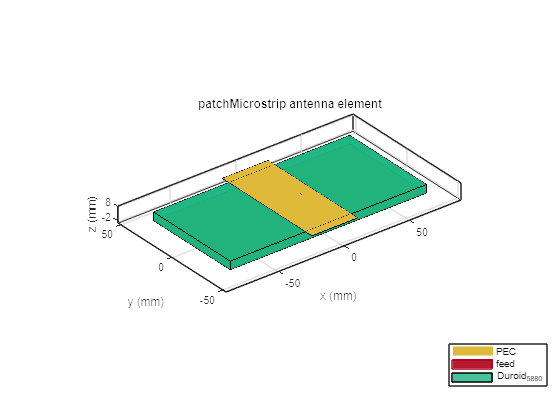

%%% E' possibile creare il patch a microstriscia direttamente dallo script
%%% (senza GUI)
%%% L'antenna toolbox ha una lista di dielettrici che possiamo usare
%%% tramite comando 

% openDielectricCatalog;

%%% Posso richiedere anche le proprietà del singolo materiale

% dielectric('FR4'); 

Duroid_5880 = dielectric('Name', 'Duroid_{5880}', 'EpsilonR', epsr, 'LossTangent', tandelta, 'Thickness', h);
Micro_Patch = patchMicrostrip('FeedOffset', [Lfeed 0]);
Micro_Patch.Length = L;
Micro_Patch.Width = W;
Micro_Patch.Substrate = Duroid_5880;
show(Micro_Patch);

S = sparameters(Micro_Patch, 2.2e9:0.2e9:2.6e9);

Error using em.Material/checkRadiatorBounds
All portions of the radiating element(antenna) must lie within the boundary of the substrate.

Error in em.Material/makeAntennaDielectricMesh

Error in em.Material/makeDielectricMesh

Error in patchMicrostrip/meshGenerator (line 498)
                        [Mesh,Parts] = makeDielectricMesh(obj.Substrate,obj,Mi);

Error in em.MeshGeometry/updateMesh

Error in em.MeshGeometry/getMesh

Error in em.EmStructures/analyze

Error in 

rfplot(S);

%% Calcolando S, si nota che alla frequenza di interesse (2.4 GHz) non sta risuonando. Risuona bene invece a -10 dB

%%% Potremmo utilizzare l'ottimizzatore di Matlab (SADEA: surrogate model
%%% assisted differential evolution for antenna synthesis). Si tratta di un
%%% algoritmo genetico che di solito converge con un centinaio di
%%% iterazioni (implementarlo con 150-200 iterazioni). 

% optimizedelement = optimize(element, frequency, objectivefunction, propertynames, bounds);

%%% Possiamo massimizzare guadagno, front to back ratio, massimizzare
%%% bandwidth, minimizzarla, massimizzare il SLL. Possiamo anche mettere
%%% dei vincoli sulle proprietà dell'antenna. Si possono anche dare dei
%%% pesi alle quantità da ottimizzare

OPtimize_Micro_Patch = optimize(Micro_Patch, f, 'minimizeBandwidth', {'Length', 'Width'}, {L/2 W/2}, 'Iterations', 10, 'UseParallel', true);

%%% Possiamo anche portare patch manualmente in risonanza osservando che la
%%% curva scende verso destra, devo scendere sotto i - 1dB

%%% Potremmo anche fare un ciclo manualmente. Dobbiamo vedere la variabile
%%% S che è una struttura di cui i valori del coefficiente di riflessione
%%% sono nella tabella S.Parameters. Sono numeri complessi, per cui dovrei
%%% fare 20*log_{10}S

20*log10(S.Parameters(i)); %% estrazione del valore

%%% STRUTTURE CUSTOM

%%% Per generarle possiamo creare rettangoli, cerchi e sottrarli
R1 = em.internal.makerectangl(0.34,0.34);
Slotted_Patch_Custom = customAntennaGeometry('Boundary', {R1', C1'}, 'Operation', 'P1-P2');
C1 = em.internal.makecircle(0.01);

R2 = em.internal.makerectangle(0.05,0.05);
Slotted_PAtch_Custom = customAntennaGeometry('Boundary', {R1',R2'}, 'Operation', 'P1-P2');
